% Load data from the new URL
url = 'https://raw.githubusercontent.com/Alex-Varghese/MATLAB/refs/heads/main/heart_2020_cleaned.csv';
opts = detectImportOptions(url);
df = readtable(url, opts);

% Rename the target column (adjust if target column name is known)
df.Properties.VariableNames{strcmp(df.Properties.VariableNames, 'HeartDisease')} = 'target';

% Ensure all predictors are numeric
X = removevars(df, 'target'); % Features
categorical_vars = varfun(@iscategorical, X, 'OutputFormat', 'uniform');
string_vars = varfun(@isstring, X, 'OutputFormat', 'uniform');
cell_vars = varfun(@iscell, X, 'OutputFormat', 'uniform'); % Identify cell array columns

% Convert categorical, string, and cell variables to numerical encoding
for i = find(categorical_vars | string_vars | cell_vars)
    if cell_vars(i)
        % Convert cell arrays to categorical first, then to double
        X.(i) = double(categorical(X.(i)));
    else
        % Convert directly to numerical
        X.(i) = double(categorical(X.(i)));
    end
end

% Convert the table to numeric format if necessary
X = varfun(@double, X);

% Process the target variable (binary or categorical encoding)
if iscell(df.target) || iscategorical(df.target)
    target_categories = categories(categorical(df.target));
    df.target = double(categorical(df.target)) - 1; % Encode as 0, 1, 2, ...
end
y = df.target; % Target variable

% Split data into training and testing sets
cv = cvpartition(height(df), 'HoldOut', 0.2);
X_train = X(training(cv), :);
y_train = y(training(cv), :);
X_test = X(test(cv), :);
y_test = y(test(cv), :);

% Decision Tree Regression
dt = fitrtree(X_train, y_train);

% Predictions
y_train_pred = predict(dt, X_train);
y_test_pred = predict(dt, X_test);

% Calculate Mean Squared Error and R2
train_mse = mean((y_train - y_train_pred).^2);
train_r2 = 1 - sum((y_train - y_train_pred).^2) / sum((y_train - mean(y_train)).^2);
test_mse = mean((y_test - y_test_pred).^2);
test_r2 = 1 - sum((y_test - y_test_pred).^2) / sum((y_test - mean(y_test)).^2);

% Display results
disp(['Decision Tree Mean Squared Error (Train): ', num2str(train_mse)]);

Decision Tree Mean Squared Error (Train): 0.032216


disp(['Decision Tree R2 (Train): ', num2str(train_r2)]);

Decision Tree R2 (Train): 0.58861


disp(['Decision Tree Mean Squared Error (Test): ', num2str(test_mse)]);

Decision Tree Mean Squared Error (Test): 0.10365


disp(['Decision Tree R2 (Test): ', num2str(test_r2)]);

Decision Tree R2 (Test): -0.3271


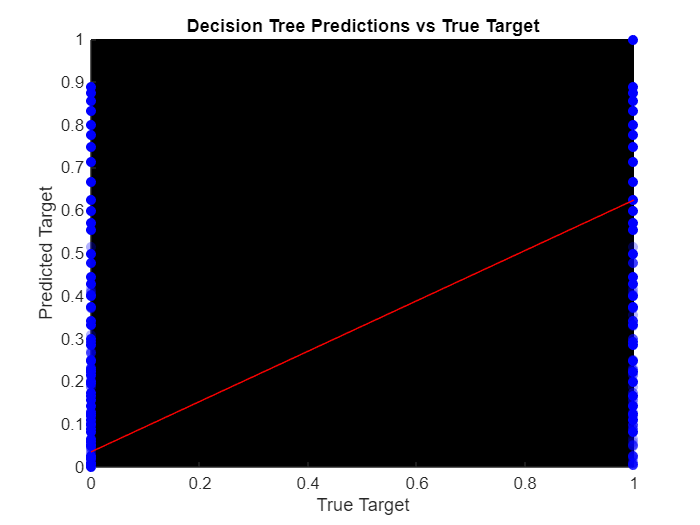


% Plot predictions vs actual
figure;
scatter(y_train, y_train_pred, 'filled', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'none', 'MarkerFaceAlpha', 0.3); % Blue
hold on;
p = polyfit(y_train, y_train_pred, 1);
yfit = polyval(p, y_train);
plot(y_train, yfit, 'r'); % Red
xlabel('True Target');
ylabel('Predicted Target');
title('Decision Tree Predictions vs True Target');
set(gca, 'Color', 'k'); % Black background


% Prediction for new input data
% Adjust input_data to match the dataset's features
input_data = [22.59,1,0,0,0,30,1,70-74,0.5,1,5,8,0,0,0]; % Example with 15 features
input_data_reshaped = reshape(input_data, 1, []);
numeric_prediction = predict(dt, input_data_reshaped);

% Map numerical prediction to categories
if exist('target_categories', 'var')
    risk_levels = target_categories; % Use categories from encoding step
    predicted_risk = risk_levels{round(numeric_prediction) + 1};
    disp(['The risk level for the patient is: ', predicted_risk, '.']);
else
    disp(['Predicted target value: ', num2str(numeric_prediction)]);
end

The risk level for the patient is: No.
